close all;
clear variables;

## Калибровка

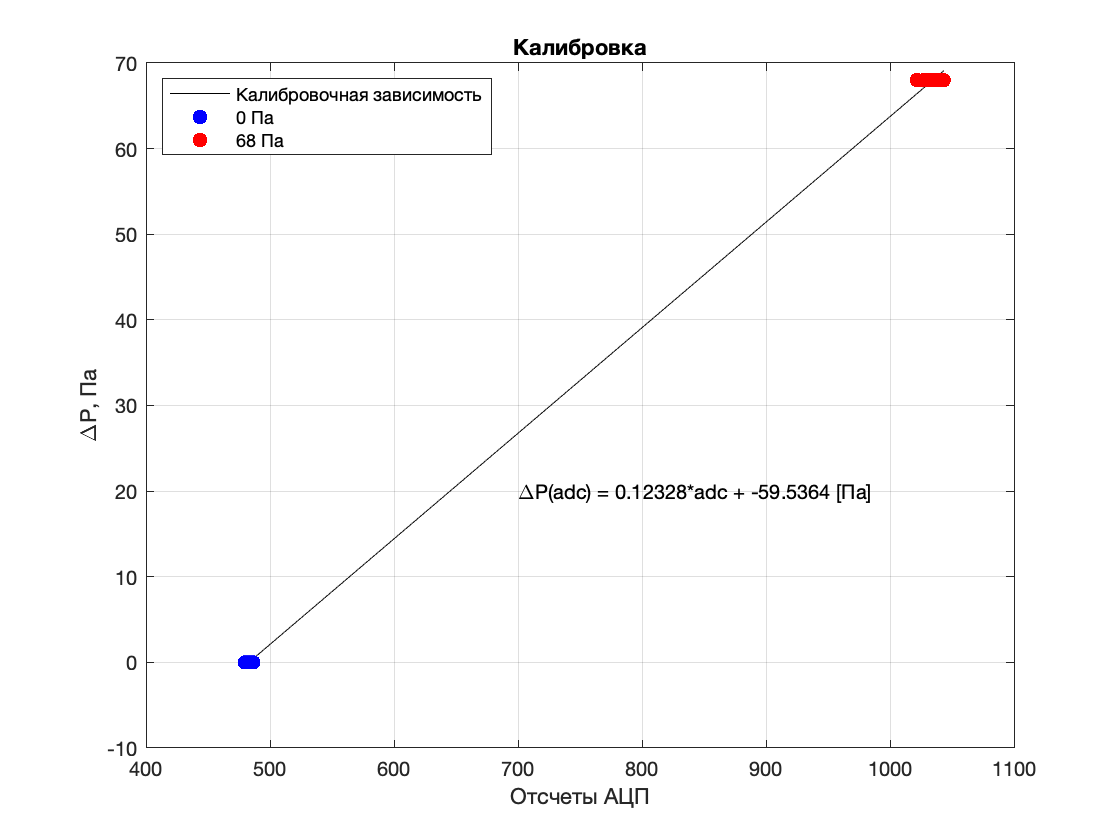

calib = load('experimentData/calib.dat');
calibzero = load('experimentData/calibzero.dat');

calib = calib(:, 2);
calibzero = calibzero(:, 2);

manometrValue = 68;

calibP = ones(1, length(calib))' .* manometrValue;
calibzeroP = zeros(1, length(calibzero))';

adc = [calibzero; calib];
pressureCalib = [calibzeroP; calibP];

c = polyfit(adc, pressureCalib, 1);

f1 = figure();
plot(adc, polyval(c, adc), 'Color','k');
grid on;
title('Калибровка');
ylabel('\DeltaP, Па');
xlabel('Отсчеты АЦП');
hold on;
plot(calibzero, calibzeroP, 'b.', 'MarkerSize', 20);
plot(calib, calibP, 'r.', 'MarkerSize', 20);

legend('Калибровочная зависимость', '0 Па', '68 Па', 'Location', 'NorthWest');
text(700, 20, ['\DeltaP(adc) = ',num2str(c(1)),'*adc + ', num2str(c(2)), ' [Па]']);

saveas(f1, 'calibration.png');

## Загрузка данных

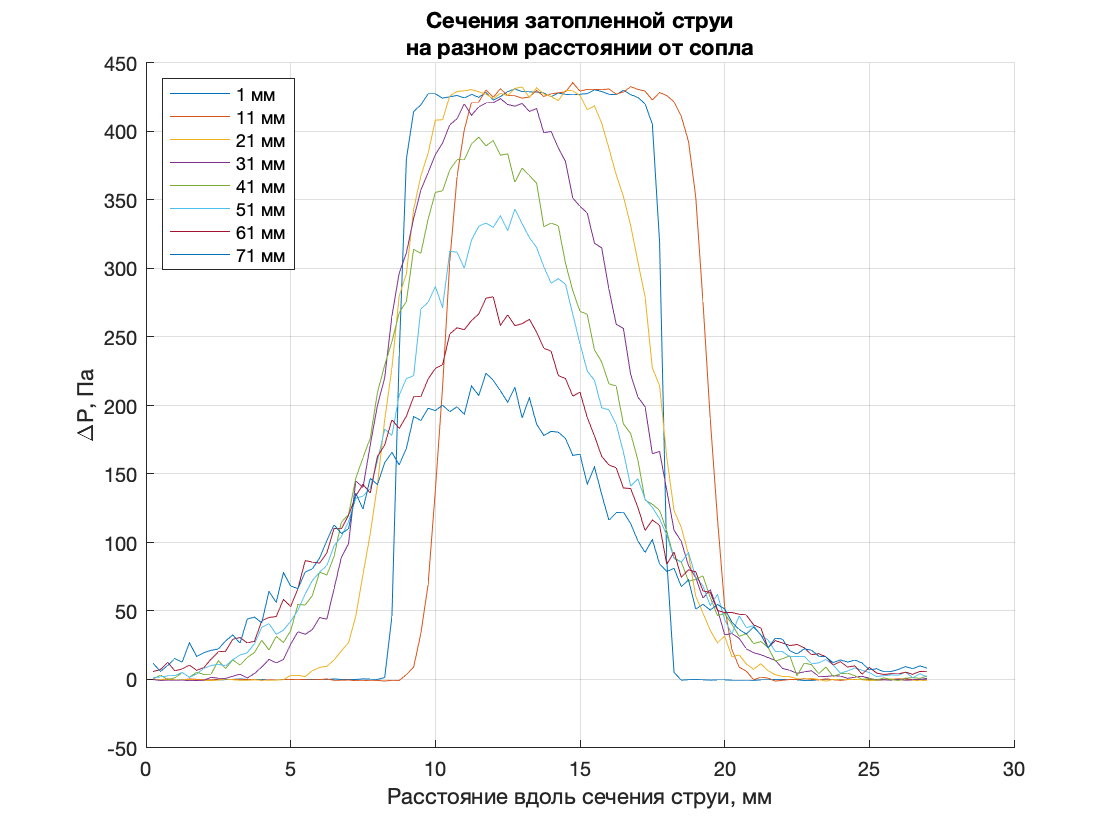

mm01 = load('experimentData/01mm.dat');
mm11 = load('experimentData/11mm.dat');
mm21 = load('experimentData/21mm.dat');
mm31 = load('experimentData/31mm.dat');
mm41 = load('experimentData/41mm.dat');
mm51 = load('experimentData/51mm.dat');
mm61 = load('experimentData/61mm.dat');
mm71 = load('experimentData/71mm.dat');

dx = 0.25; % мм
x = mm01(:, 1)' * 0.25;

p01 = polyval(c, mm01(:, 2));
p11 = polyval(c, mm11(:, 2));
p21 = polyval(c, mm21(:, 2));
p31 = polyval(c, mm31(:, 2));
p41 = polyval(c, mm41(:, 2));
p51 = polyval(c, mm51(:, 2));
p61 = polyval(c, mm61(:, 2));
p71 = polyval(c, mm71(:, 2));

pressure = [p01, p11, p21, p31, p41, p51, p61, p71];
zNames = {'1 мм'; '11 мм'; '21 мм'; '31 мм'; '41 мм'; '51 мм'; '61 мм'; '71 мм'};
z = [1, 11, 21, 31, 41, 51, 61, 71];

f2 = figure();
hold on;
grid on;
title({'Сечения затопленной струи', 'на разном расстоянии от сопла'});
ylabel('\DeltaP, Па');
xlabel('Расстояние вдоль сечения струи, мм');

for i = 1:size(pressure, 2)
    plot(x, pressure(:, i), 'DisplayName', zNames{i});
end

legend('Location', 'NorthWest');

saveas(f2, 'pressure.png');

## Сдвиг к центру сопла

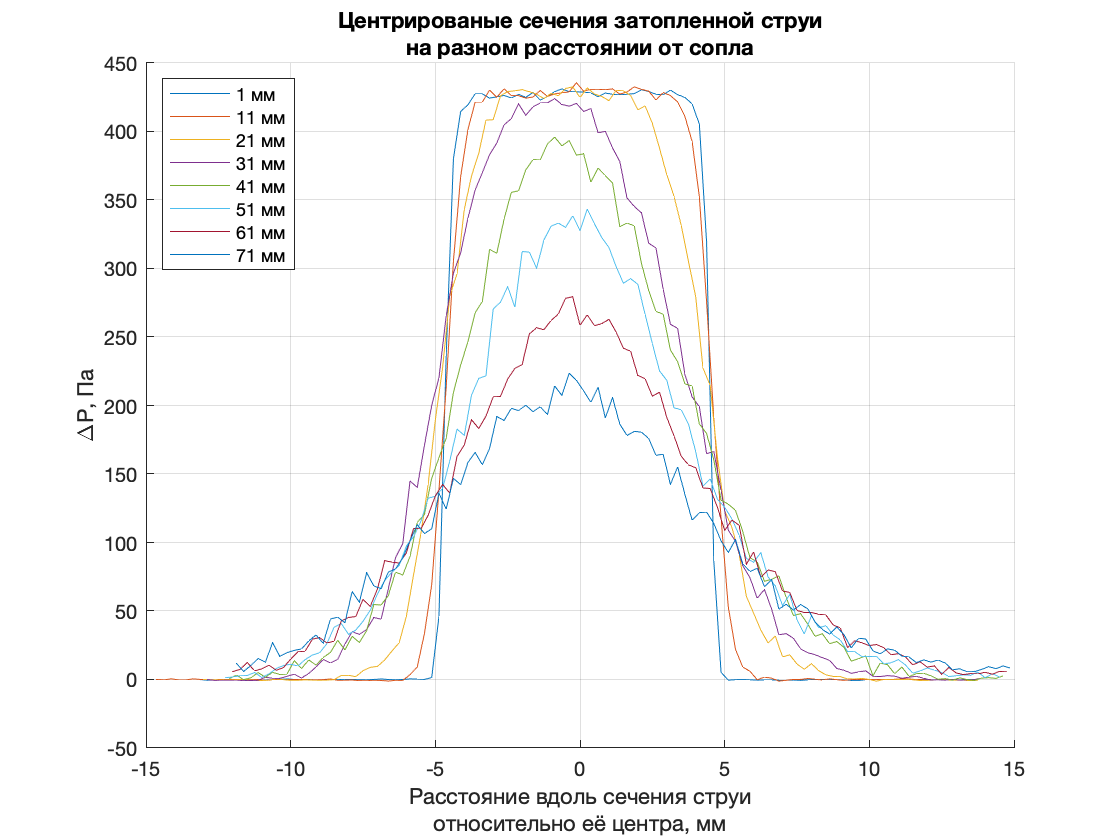

f3 = figure();
hold on;
grid on;
title({'Центрированые сечения затопленной струи', 'на разном расстоянии от сопла'});
ylabel('\DeltaP, Па');
xlabel({'Расстояние вдоль сечения струи', 'относительно её центра, мм'});

xCentered = zeros(size(pressure));
offset = 50;

for i = 1:size(pressure, 2)
    right = x(find(pressure(:, i) > offset, 1, 'last'));
    left = x(find(pressure(:, i) > offset, 1));
    
    center = left + (right - left) / 2;
    xCentered(:, i) = x - center;
    
    plot(xCentered(:, i), pressure(:, i), 'DisplayName', zNames{i});
end

legend('Location', 'NorthWest');

saveas(f3, 'centered.png');

## Расчёт скоростей

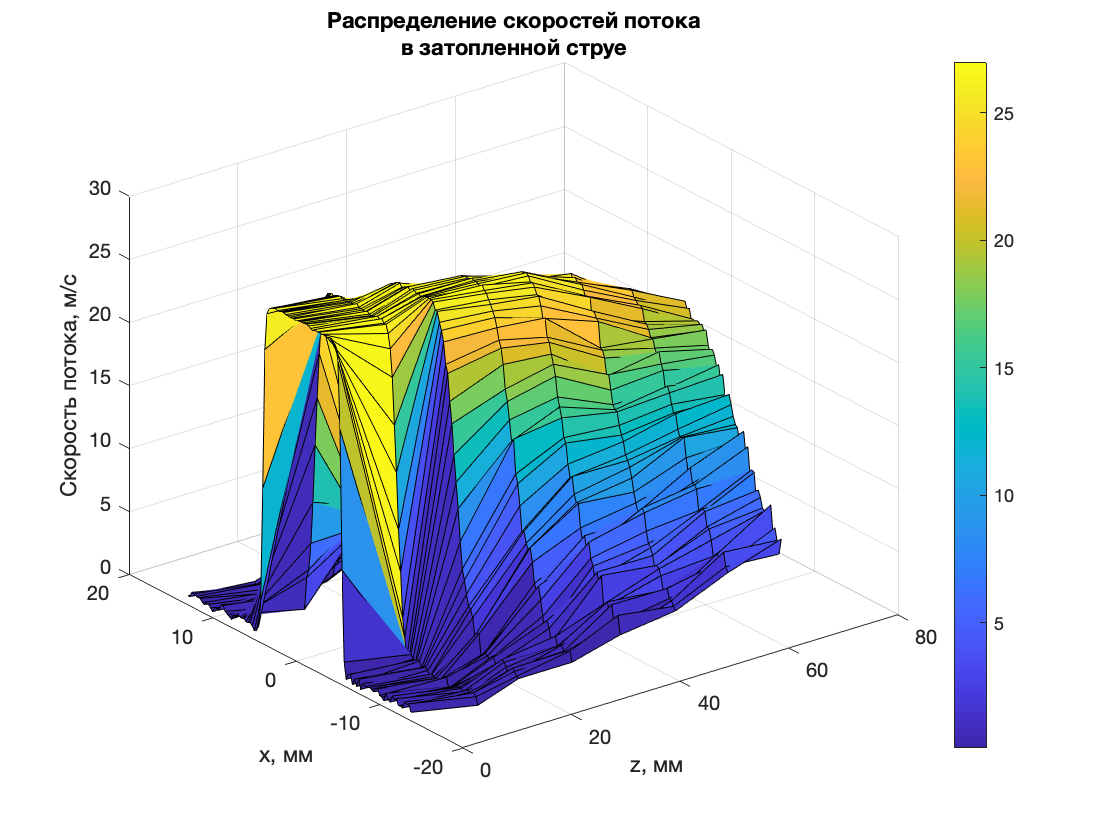

density = 1.2;
velocity = sqrt(2 * abs(pressure) / density);

f4 = figure();
surf(z, xCentered, velocity);
title({'Распределение скоростей потока', 'в затопленной струе'});
xlabel('z, мм');
ylabel('x, мм');
zlabel('Скорость потока, м/с');
colorbar;

saveas(f4, 'surface.png');

## Расчёт расхода

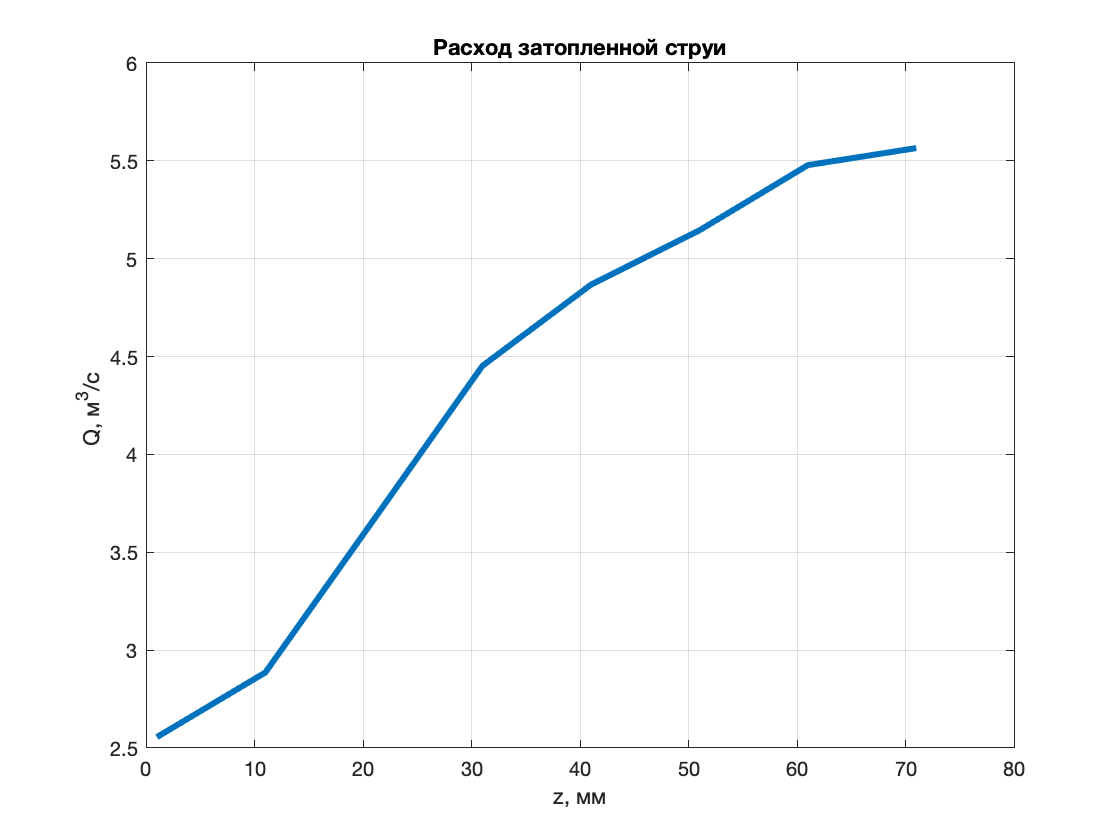

dMass = 2 * pi * density * (velocity .* abs(xCentered)) * (dx / 1000);
q = sum(dMass, 1) / 2;

f5 = figure();
plot(z, q, 'LineWidth', 3);
grid on;

title('Расход затопленной струи');
xlabel('z, мм');
ylabel('Q, м^3/с ');

saveas(f5, 'jet-flow.png');